# Lift Mesh Xfoil

clear; close; clc;

## Define Parameters

alt = 1000; % altitude above sea level (m)
Re = 5e5; % Reynolds number (~)
M = 0; % Mach Number (~) -> 0 for incompressible

% define angle of attacks to measure
alpha_min = -45% minimum anlge of attack to measure (degrees)

alpha_min = -45

alpha_centre = 0; % minimum anlge of attack to measure (degrees)
alpha_max = 45; % maximum anlge of attack to measure (degrees)
n_alphas = 191; % number of angle of attacks to measure (#) -> use an odd number to include alpha = 0

% define pararemters for xfoil simulation

% define itteration limit (default 10)
iterations = 40; % xfoil itteration limit (default 10)

% define number of panels (default 160)
nPanles = 160; % (default 160 for built-in naca foils)

% define airfoils to use
airfoils = ['NACA0012';'NACA2412';'NACA4412';'NACA6412';'NACA9412'];
cambers = [0,2,4,6,9];

airfoils = ['NACA0012'; 'NACA1412'; 'NACA2412'; 'NACA3412'; 'NACA4412'; 'NACA5412'; 'NACA6412'; 'NACA7412'; 'NACA8412'; 'NACA9412'];
cambers = [0:9]*.01;

## Initialize variables

% create the space of alphas
alpha_pos = linspace(alpha_centre, alpha_max, n_alphas); % I should probably do alpha min to 0 and 0 to alpha max then combine to ensure 0 is included
alpha_neg = linspace(alpha_centre, alpha_min, n_alphas); % the negative alphas (must be ordered like this for stable solutions)

% extra parameters for xfoil
% Turn options into commands executable by xfoil to be passed as strings
iterStr = sprintf("oper iter %u", iterations); % String containing iteration opertions for xfoil
panelStr = sprintf("ppar n %u", nPanles); % number of panles to be used in xfoil's airfoil mesh

% number of cambers available
% TODO: flip and mirror these so that I can put these as negative cambers
n_cambers = size(airfoils,1);

% Define the Lift Mesh  (alpha_index, camber_index, value_type)
% value types: 1, alpha, 2 camber, 3 C_l
LiftMesh_posCamb = zeros(2*n_alphas-1, n_cambers, 3);

## Test aifoil generation

% note the blending of airfoil feature in matlab if i want to blend between
% a selig 1223 and a symmetric airfoil

% produce airfoil data as a function of angle of attack

% initialize loop variables
%polars

figure; hold on;
for i = 1:size(airfoils,1)
    airfoil = airfoils(i,:);
% NOTE: must use '' rather than "" for NACA foils
% return only polar to save memory if possible also is more relyable at
% deleting the .dat files
polar = xfoil(airfoil, alpha_pos, Re, M, iterStr, panelStr, "oper vpar init");
% plot airfoil simulation results

% store value for positive angles of attack
polars(i,1) = polar;


polar = xfoil(airfoil, alpha_neg, Re, M, iterStr, panelStr, "oper vpar init");
polars(i,2) = polar;


% plotlift curve
%plot(polar.alpha, polar.CL, "o-", "DisplayName", polar.name); xlabel('alpha [\circ]'); ylabel('C_L'); title(polar.name);
end

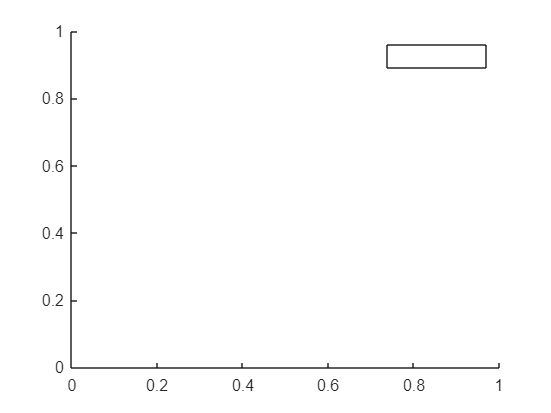

legend

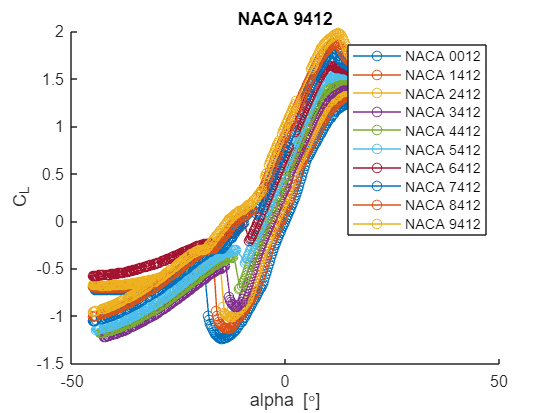


figure; hold on;
for i = 1:size(polars,1)
    %plot([polars(i,1).alpha; polars(i,2).alpha], [polars(i,1).CL;polars(i,2).CL], "o-", "DisplayName", polars(i,1).name); xlabel('alpha [\circ]'); ylabel('C_L'); title(polars(i,1).name);
    plot([flipud(polars(i,2).alpha(2:end)); polars(i,1).alpha], [flipud(polars(i,2).CL(2:end)); polars(i,1).CL], "o-", "DisplayName", polars(i,1).name); xlabel('alpha [\circ]'); ylabel('C_L'); title(polars(i,1).name);
end
legend

## Save as lift mesh

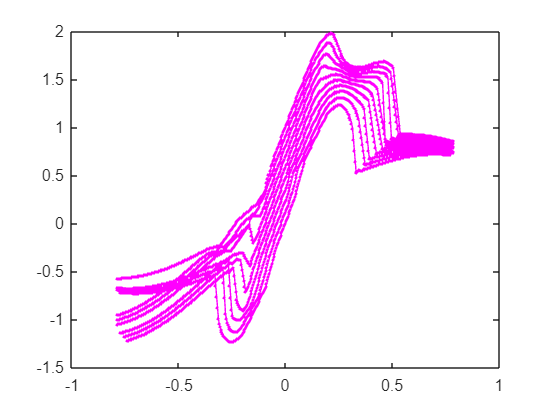

% produce the lift mesh at each camber (Might be able to vectorie by
% creating a meshgrid of alphas and cambers and then using griddata

alpha_desired = [fliplr(alpha_neg(2:end)), alpha_pos]; % alphas to query

for i = 1:n_cambers
    % assemble the computed data
    alpha_modeled = [flipud(polars(i,2).alpha(2:end)); polars(i,1).alpha];
    C_L_modeled = [flipud(polars(i,2).CL(2:end)); polars(i,1).CL];
    
    % define desired data
    alpha_desired = [fliplr(alpha_neg(2:end)), alpha_pos]; % alphas to query
    C_L_desired = interp1(alpha_modeled, C_L_modeled, alpha_desired); % C_L at queried alphas
    
    % store in lift mesh
    LiftMesh_posCamb(:,i,1) = alpha_desired;
    LiftMesh_posCamb(:,i,2) = ones(size(LiftMesh_posCamb(:,i,2))) * cambers(i);
    LiftMesh_posCamb(:,i,3) = C_L_desired;
end

% conver to radians
LiftMesh_posCamb(:,:,1) = deg2rad(LiftMesh_posCamb(:,:,1));

% plot the lift mesh
figure
plot(LiftMesh_posCamb(:,:,1), LiftMesh_posCamb(:,:,3),".-m");


% % produce a plot for a single angle of attack
% figure;
% % pressure distribution plot
% subplot(3,1,[1 2]);
% plot(foil(1).xcp(:,end), foil(1).cp(:,end));
% xlabel("x"); ylabel("C_p"); title(sprintf('%s @ %g\\circ', polar.name, foil(1).alpha(end)));
% set(gca, "ydir", "reverse");
% % airfoil plot
% subplot(3,1,3);
% I = foil(1).x(:,end)<=1;
% plot(foil(1).x(I,end), foil(1).y(I,end)); axis("equal");
% xlabel("x"); ylabel("y");


## Produce negative camber airfoils

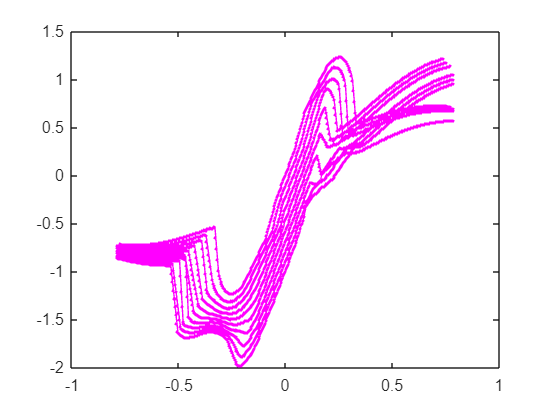

% procues Lift Mesh for negative camber airfoils
% if C_L = f(alpha) for a positive cmaber airfoil then the negative camber
% equivalent has C_L = -f(-alpha)

LiftMesh_negCamb(:,:,1) = -flipud(fliplr(LiftMesh_posCamb(:,:,1)));
LiftMesh_negCamb(:,:,2) = -fliplr(LiftMesh_posCamb(:,:,2));
LiftMesh_negCamb(:,:,3) = -flipud(fliplr(LiftMesh_posCamb(:,:,3)));

figure
plot(LiftMesh_negCamb(:,:,1), LiftMesh_negCamb(:,:,3),".-m");

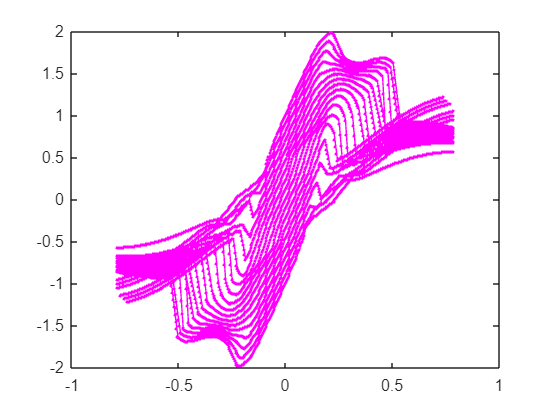


% combine the two lift meshes
LiftMesh(:,:,1) = [LiftMesh_negCamb(:,1:end-1,1), LiftMesh_posCamb(:,:,1)];
LiftMesh(:,:,2) = [LiftMesh_negCamb(:,1:end-1,2), LiftMesh_posCamb(:,:,2)];
LiftMesh(:,:,3) = [LiftMesh_negCamb(:,1:end-1,3), LiftMesh_posCamb(:,:,3)];

%save the lift mesh
save("liftMesh_Xfoil","LiftMesh");

figure
plot(LiftMesh(:,:,1), LiftMesh(:,:,3),".-m");

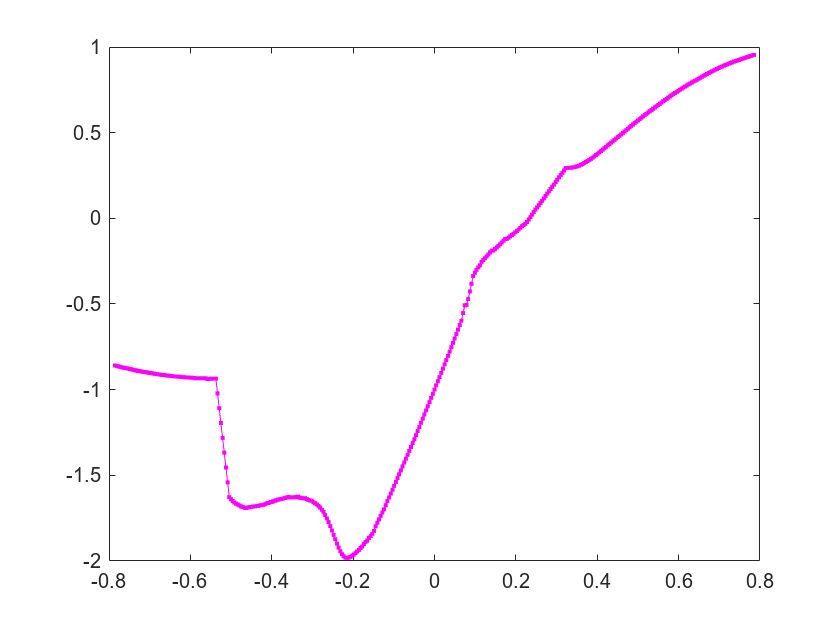


figure;
for i = 1:2*n_cambers-1
    plot(LiftMesh(:,i,1), LiftMesh(:,i,3),".-m");
    drawnow
    xlim([-.8,.8]); ylim([-2,2]);
end